# 7.1 线性相位 FIR 的四种类型：从 h(n) 的对称性得到幅度函数 H(ω) 与相位 θ(ω)，教材例 7.1—7.4 逐一核对

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if isempty(here), here = pwd; end
outdir = fullfile(here, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 四个例子：教材例 7.1（1 型）、7.2（2 型）、7.3（3 型）、7.4（4 型）

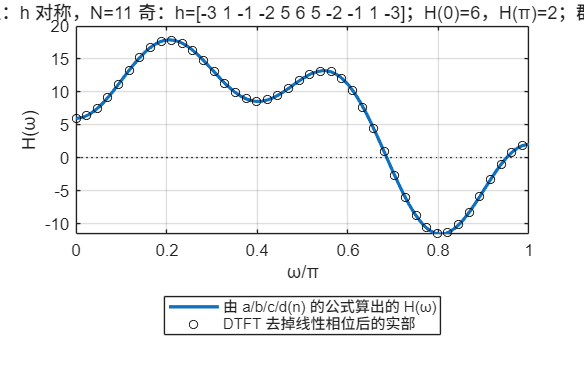

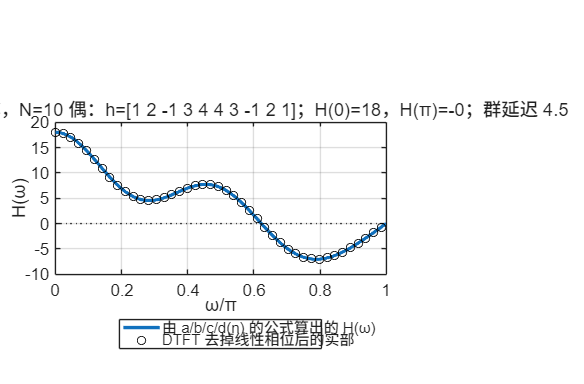

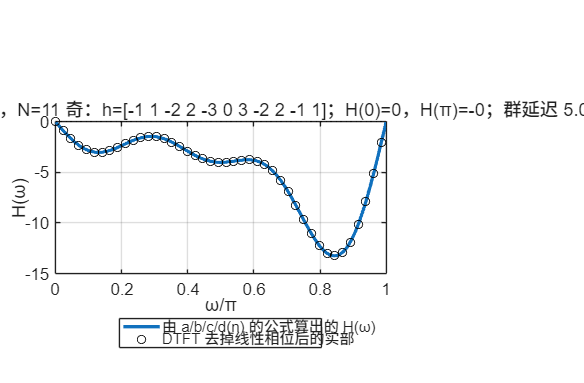

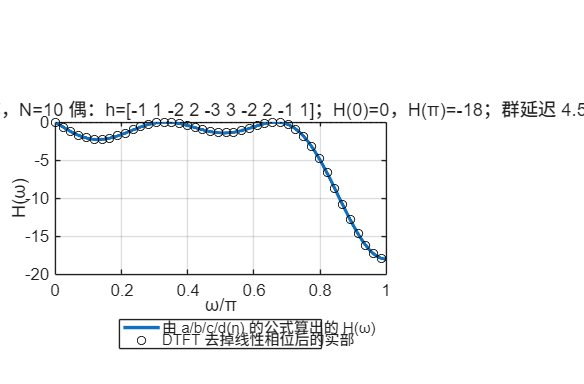

hs = {[-3 1 -1 -2 5 6 5 -2 -1 1 -3], [1 2 -1 3 4 4 3 -1 2 1], [-1 1 -2 2 -3 0 3 -2 2 -1 1], [-1 1 -2 2 -3 3 -2 2 -1 1]};
names = {'1 型：h 对称，N=11 奇', '2 型：h 对称，N=10 偶', '3 型：h 反对称，N=11 奇', '4 型：h 反对称，N=10 偶'};
w = linspace(0, pi, 1024);
Hw = cell(1, 4); Hchk = cell(1, 4); coef = cell(1, 4); errs = zeros(1, 4); H0 = zeros(1, 4); Hpi = zeros(1, 4); tau = zeros(1, 4);
for t = 1:4
    h = hs{t}; N = numel(h); tau(t) = (N - 1)/2;
    H = polyval(fliplr(h), exp(-1i*w));                              % 直接算 DTFT：Σ h(n) e^{-jωn}
    switch t
        case 1   % 式 (7.1.10)—(7.1.12)：a(0)=h((N−1)/2)，a(n)=2h((N−1)/2−n)，H(ω)=Σ a(n)cos(nω)
            L = (N - 1)/2; a = [h(L + 1), 2*h(L:-1:1)]; n = 0:L;
            Hw{t} = a*cos(n.'*w); coef{t} = a; ph = -(N - 1)*w/2;
        case 2   % 式 (7.1.14)(7.1.15)：b(n)=2h(N/2−n)，H(ω)=Σ b(n)cos((n−1/2)ω)
            L = N/2; b = 2*h(L:-1:1); n = 1:L;
            Hw{t} = b*cos((n.' - 0.5)*w); coef{t} = b; ph = -(N - 1)*w/2;
        case 3   % 式 (7.1.17)(7.1.18)：c(n)=2h((N−1)/2−n)，H(ω)=Σ c(n)sin(nω)，相位多 π/2
            L = (N - 1)/2; c = 2*h(L:-1:1); n = 1:L;
            Hw{t} = c*sin(n.'*w); coef{t} = c; ph = -(N - 1)*w/2 + pi/2;
        case 4   % 式 (7.1.19)(7.1.20)：d(n)=2h(N/2−n)，H(ω)=Σ d(n)sin((n−1/2)ω)，相位多 π/2
            L = N/2; d = 2*h(L:-1:1); n = 1:L;
            Hw{t} = d*sin((n.' - 0.5)*w); coef{t} = d; ph = -(N - 1)*w/2 + pi/2;
    end
    Hchk{t} = real(H .* exp(-1i*ph));                                % 把线性相位除掉，剩下的应是实数 H(ω)
    errs(t) = max(abs(H - Hw{t}.*exp(1i*ph)));                       % H(e^{jω}) = H(ω) e^{jθ(ω)} 是否成立
    H0(t) = Hw{t}(1); Hpi(t) = Hw{t}(end);
end
% 每类的固有零点：2 型 H(π)=0；3 型 H(0)=H(π)=0；4 型 H(0)=0
zeroFacts = [abs(Hpi(2)), abs(H0(3)), abs(Hpi(3)), abs(H0(4))];

if ~LIVE, f1 = figure('Name','01 线性相位四型','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
for t = 1:4
    newpanel(); plot(w/pi, Hw{t}, 'LineWidth', 2); hold on; plot(w(1:24:end)/pi, Hchk{t}(1:24:end), 'ko', 'MarkerSize', 5);
    yline(0, 'k:'); grid on; xlabel('ω/π'); ylabel('H(ω)');
    circ = '①②③④';
    title(sprintf('%s %s：h=[%s]；H(0)=%.0f，H(π)=%.0f；群延迟 %.1f', circ(t), names{t}, strjoin(compose('%g', hs{t}), ' '), H0(t), Hpi(t), tau(t)));
    legend('由 a/b/c/d(n) 的公式算出的 H(ω)', 'DTFT 去掉线性相位后的实部');
end

if ~LIVE, sgtitle('线性相位 FIR：h(n) 对称或反对称 ⇒ H(e^{jω})=H(ω)e^{jθ(ω)}，θ 是 ω 的直线；四种类型各有固有零点'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '01-linear-phase-types.png'), 'Resolution', 150); end

## 教师核验

assert(all(errs < 1e-10), 'H(ω)e^{jθ} 与 DTFT 不一致');
assert(all(zeroFacts < 1e-10), '固有零点不符');
assert(abs(H0(1) - sum(hs{1})) < 1e-12 && abs(H0(2) - sum(hs{2})) < 1e-12, 'H(0) 应等于 Σh');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'err_type1_4', errs, 'H0_type1_4', H0, 'Hpi_type1_4', Hpi, 'group_delay', tau, ...
    'a_type1', coef{1}, 'b_type2', coef{2}, 'c_type3', coef{3}, 'd_type4', coef{4}, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-linear-phase-types.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

       matlab_version: '25.2.0.3360999 (R2025b) Update 7'
               run_at: '2026-09-18 22:16:20'
          err_type1_4: [1.6086e-14 9.2729e-15 1.4321e-14 1.9214e-14]
           H0_type1_4: [6 18 0 0]
          Hpi_type1_4: [2 -1.8370e-15 -5.3884e-15 -18]
          group_delay: [5 4.5000 5 4.5000]
              a_type1: [6 10 -4 -2 2 -6]
              b_type2: [8 6 -2 4 2]
              c_type3: [-6 4 -4 2 -2]
              d_type4: [-6 4 -4 2 -2]
    all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_mcnta\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end